# Representational Similarity Analysis tutorial

Author: Choong-Wan Woo (Sungkyunkwan University) [https://cocoanlab.github.io/](https://cocoanlab.github.io/)

Date: 2019/8/17 @ KHBM 2019 Summer school

## Dataset

- from Woo et al., 2014, Nat Comms (download: [https://cocoanlab.github.io/pdfs/Woo_2014_NatComms.pdf](https://cocoanlab.github.io/pdfs/Woo_2014_NatComms.pdf))

- N = 59

- There were two types of tasks, and in each task, there were two conditions (2 x 2 design)

- -- Physical pain task (Heat, Warmth conditions)

- -- Social pain task (Rejection, Friends conditions)

## Analysis plan

- Computing RDMs for each participant, for each region (4 ROIs: aINS, dACC, S2/dpINS, TPJ),  and visualize the RDMs

- Comparing brain and model RDMs: We have two model RDMs: physical vs. social, aversive vs. non-aversive, and 4 ROIs

- Statistical inference: Using the neurosync mask that Woo 2014 used, we will do statistical inference

## Step 1: Computing and visualizing RDMs

### Basic setup

% directory setup
basedir = '/Users/clinpsywoo/Dropbox/github/khbm2019_RSA_tutorial/tutorial';
% you need to change the first part of the path into your path directories

datdir = fullfile(basedir, 'data', 'contrast_images');

roi_masks = filenames(fullfile(basedir, 'masks', '*smooth_mirror.nii'));
whole_masks = filenames(fullfile(basedir, 'masks', '*Woo2014.nii'), 'char');
% filenames is a useful function from CanlabCore toolbox

conditions = {'heat', 'warmth', 'rejection', 'friend'};

line_disp = repmat('=', 1, 50); % for display

addpath(fullfile(basedir, 'external'));


### Reading data for ROI masks

for i = 1:numel(roi_masks)
    [~, roi{i}.name] = fileparts(roi_masks{i});
    disp(line_disp);
    fprintf('Reading data from %s\n', roi{i}.name);
    disp(line_disp);
    roi{i}.heat = fmri_data(filenames(fullfile(datdir, 'heat_sub_*.nii')), roi_masks{i});
    roi{i}.warmth = fmri_data(filenames(fullfile(datdir, 'warmth_sub_*.nii')), roi_masks{i});
    roi{i}.rejection = fmri_data(filenames(fullfile(datdir, 'rejection_sub_*.nii')), roi_masks{i});
    roi{i}.friend = fmri_data(filenames(fullfile(datdir, 'friend_sub_*.nii')), roi_masks{i});
end

Reading data from S2_dpINS_smooth_mirror


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1475472 bytes
Loading image number:    59
경과 시간은 0.233853초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1475472 bytes
Loading image number:    59
경과 시간은 0.260482초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1475472 bytes
Loading image number:    59
경과 시간은 0.232150초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1475472 bytes
Loading image number:    59
경과 시간은 0.238006초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Reading data from aINS_smooth_mirror


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 691008 bytes
Loading image number:    59
경과 시간은 0.228889초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 691008 bytes
Loading image number:    59
경과 시간은 0.266703초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 691008 bytes
Loading image number:    59
경과 시간은 0.248521초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 691008 bytes
Loading image number:    59
경과 시간은 0.263496초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Reading data from dACC_smooth_mirror


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 434476 bytes
Loading image number:    59
경과 시간은 0.233997초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 434476 bytes
Loading image number:    59
경과 시간은 0.252351초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 434476 bytes
Loading image number:    59
경과 시간은 0.255809초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 434476 bytes
Loading image number:    59
경과 시간은 0.266063초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Reading data from tpj_smooth_mirror


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 330872 bytes
Loading image number:    59
경과 시간은 0.267580초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 330872 bytes
Loading image number:    59
경과 시간은 0.288385초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 330872 bytes
Loading image number:    59
경과 시간은 0.275797초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 330872 bytes
Loading image number:    59
경과 시간은 0.291910초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


### Reading data for whole-brain mask

for cond_i = 1:numel(conditions)
    [~, whole.name] = fileparts(whole_masks);
    disp(line_disp);
    fprintf('Reading data from the whole-brain mask for %s\n', conditions{cond_i});
    disp(line_disp);
    eval(['whole.' conditions{cond_i} ' = fmri_data(filenames(fullfile(datdir, ''' conditions{cond_i} '_sub_*.nii'')), whole_masks);']);
end

Reading data from the whole-brain mask for heat


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 15975312 bytes
Loading image number:    59
경과 시간은 0.398826초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Reading data from the whole-brain mask for warmth


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 15975312 bytes
Loading image number:    59
경과 시간은 0.380220초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Reading data from the whole-brain mask for rejection


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 15975312 bytes
Loading image number:    59
경과 시간은 0.427094초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Reading data from the whole-brain mask for friend


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 15975312 bytes
Loading image number:    59
경과 시간은 0.438862초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


### Computing RDMs for each region and for each individual

n_subj = size(roi{1}.heat.dat,2);

for roi_i = 1:numel(roi)
    if roi_i == 1, disp(line_disp); fprintf('Computing RDMs for ROIs...\n'); end
    roi{roi_i}.rdms = zeros(4,4);
    for cond_i = 1:numel(conditions)
        for cond_j = 1:numel(conditions)
            if cond_i ~= cond_j
                for subj_i = 1:n_subj

                    eval(['roi{roi_i}.rdms(cond_i,cond_j,subj_i) = 1-corr(roi{roi_i}.' ...
                        conditions{cond_i} '.dat(:,subj_i), roi{roi_i}.' ...
                        conditions{cond_j} '.dat(:,subj_i));']);
                    
                    roi{roi_i}.rdms(cond_j,cond_i,subj_i) = roi{roi_i}.rdms(cond_i,cond_j,subj_i); % to make RDMs symmetric
                    
                end
            end
        end
    end
    if roi_i == numel(roi), fprintf('DONE.\n'); disp(line_disp); end
end

Computing RDMs for ROIs...


DONE.




for cond_i = 1:numel(conditions)
    if cond_i == 1, disp(line_disp); fprintf('Computing RDMs for whole-brain...\n'); end
    for cond_j = 1:numel(conditions)
        if cond_i ~= cond_j
            for subj_i = 1:n_subj
                eval(['whole.rdms(cond_i,cond_j,subj_i) = 1-corr(whole.' ...
                    conditions{cond_i} '.dat(:,subj_i), whole.' ...
                    conditions{cond_j} '.dat(:,subj_i));']);
                
                whole.rdms(cond_j,cond_i,subj_i) = whole.rdms(cond_i,cond_j,subj_i); % to make RDMs symmetric
            end
        end
    end
    if cond_i == numel(conditions), fprintf('DONE.\n'); disp(line_disp); end
end

Computing RDMs for whole-brain...


DONE.


### Visualize mean RDMs

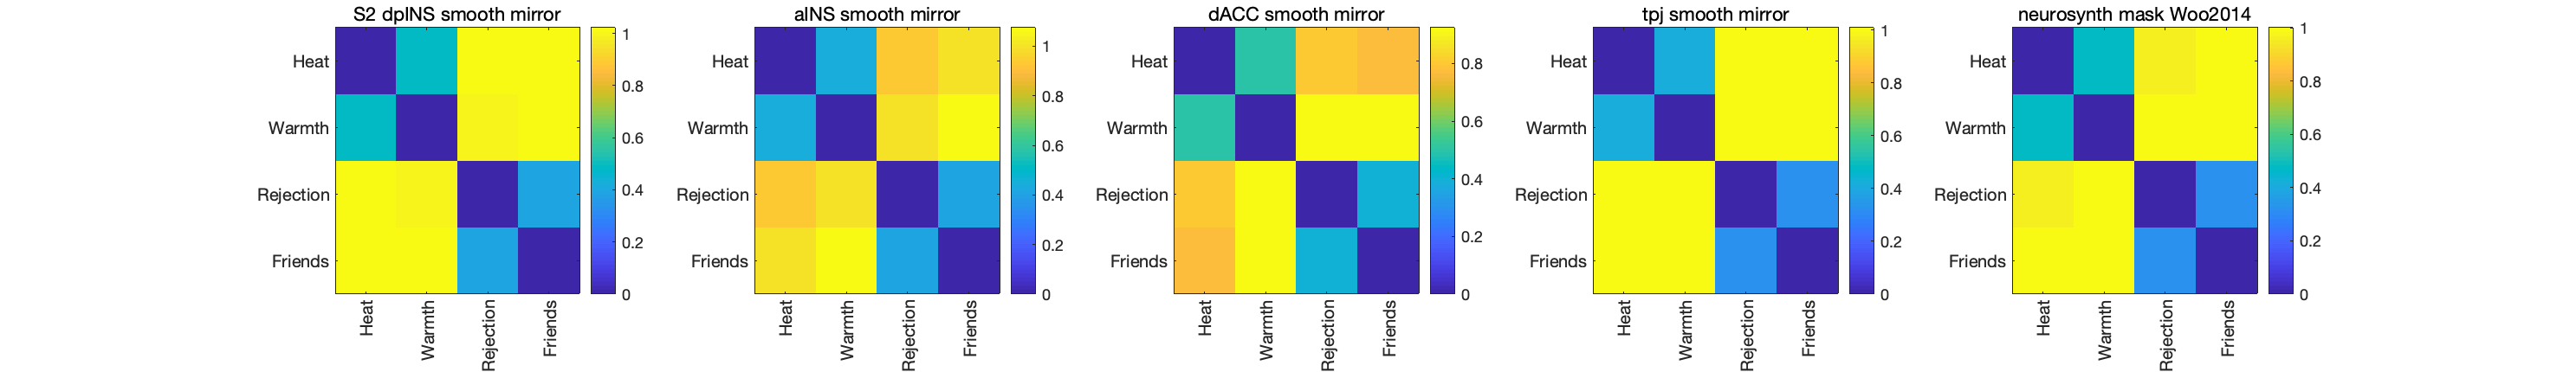

Representational Dissimilarity Matrices


figure;
set(gcf, 'position', [1         740        1487         215], 'color', 'w')
for i = 1:5
    if i == 1, disp('Representational Dissimilarity Matrices'); end
    subplot(1,5,i);
    if i ~= 5
    imagesc(mean(roi{i}.rdms,3));   
    colorbar;
    roi{i}.name(strfind(roi{i}.name, '_')) = ' ';
    title(roi{i}.name);
    else
        imagesc(mean(whole.rdms,3));   
        colorbar;
        whole.name(strfind(whole.name, '_')) = ' ';
        title(whole.name);        
    end
    set(gca, 'xticklabel', {'Heat', 'Warmth', 'Rejection', 'Friends'}, 'XTickLabelRotation', 90);
    set(gca, 'yticklabel', {'Heat', 'Warmth', 'Rejection', 'Friends'});
end

## Step 2: Comparing brain and model RDMs

### Creating model RDMs

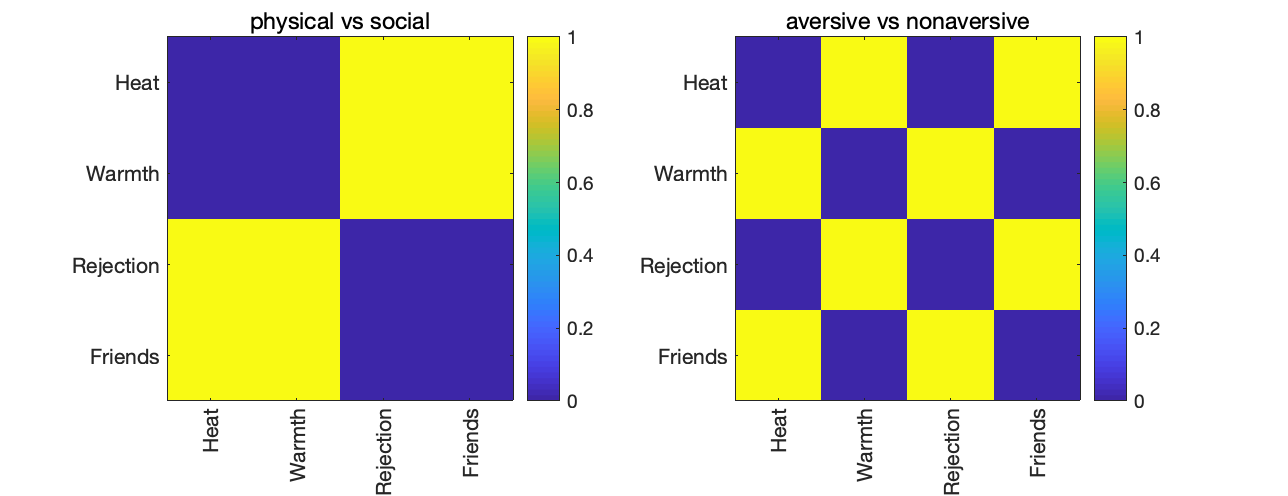


% 1. physical vs. social
model{1}.rdms = [0 0 1 1;0 0 1 1;1 1 0 0;1 1 0 0];
model{1}.name = 'physical vs social';

% 2. aversive vs. nonaversive
model{2}.rdms = [0 1 0 1;1 0 1 0;0 1 0 1;1 0 1 0];
model{2}.name = 'aversive vs nonaversive';

figure;
set(gcf, 'position', [ 1   707   644   248], 'color', 'w')

for i = 1:2
    subplot(1,2,i);
    imagesc(model{i}.rdms);
    colorbar;
    title(model{i}.name);
    set(gca, 'xtick', 1:4, 'ytick', 1:4);
    set(gca, 'xticklabel', {'Heat', 'Warmth', 'Rejection', 'Friends'}, 'XTickLabelRotation', 90);
    set(gca, 'yticklabel', {'Heat', 'Warmth', 'Rejection', 'Friends'});
end

### Comparing the ROI RDMs with the model RDMs

% ROIs
for roi_i = 1:4
    rdms.dat(:,:,roi_i) = mean(roi{roi_i}.rdms,3); % average across subjects
    rdms.names{roi_i} = roi{roi_i}.name;           % ROI names
end

% whole brain
rdms.dat(:,:,5) = mean(whole.rdms,3);
rdms.names{5} = 'whole';

% models
% 1. physical vs. social
rdms.dat(:,:,6) = model{1}.rdms;
rdms.names{6} = model{1}.name;

% 2. aversive vs. non-aversive
rdms.dat(:,:,7) = model{2}.rdms;
rdms.names{7} = model{2}.name;

% Preallocation
r_models = NaN(size(rdms.dat,3),size(rdms.dat,3));
upper_triang_idx = triu(true(4,4),1);

% Calculate Kendall's tau a (recommendation by Kriegeskorte)

for i = 1:size(rdms.dat,3)
    xx = squeeze(rdms.dat(:,:,i));
    for j = 1:size(rdms.dat,3)
        if i ~= j
            yy = squeeze(rdms.dat(:,:,j));
            r_models(i,j) = rankCorr_Kendall_taua(xx(upper_triang_idx), yy(upper_triang_idx));
        else
            r_models(i,j) = 1;
        end
    end
    rdms.flatten_dat(:,i) = xx(upper_triang_idx);
end


### Visualize the relationships among the regions and models using MDS (multidimensional scaling) and t-SNE

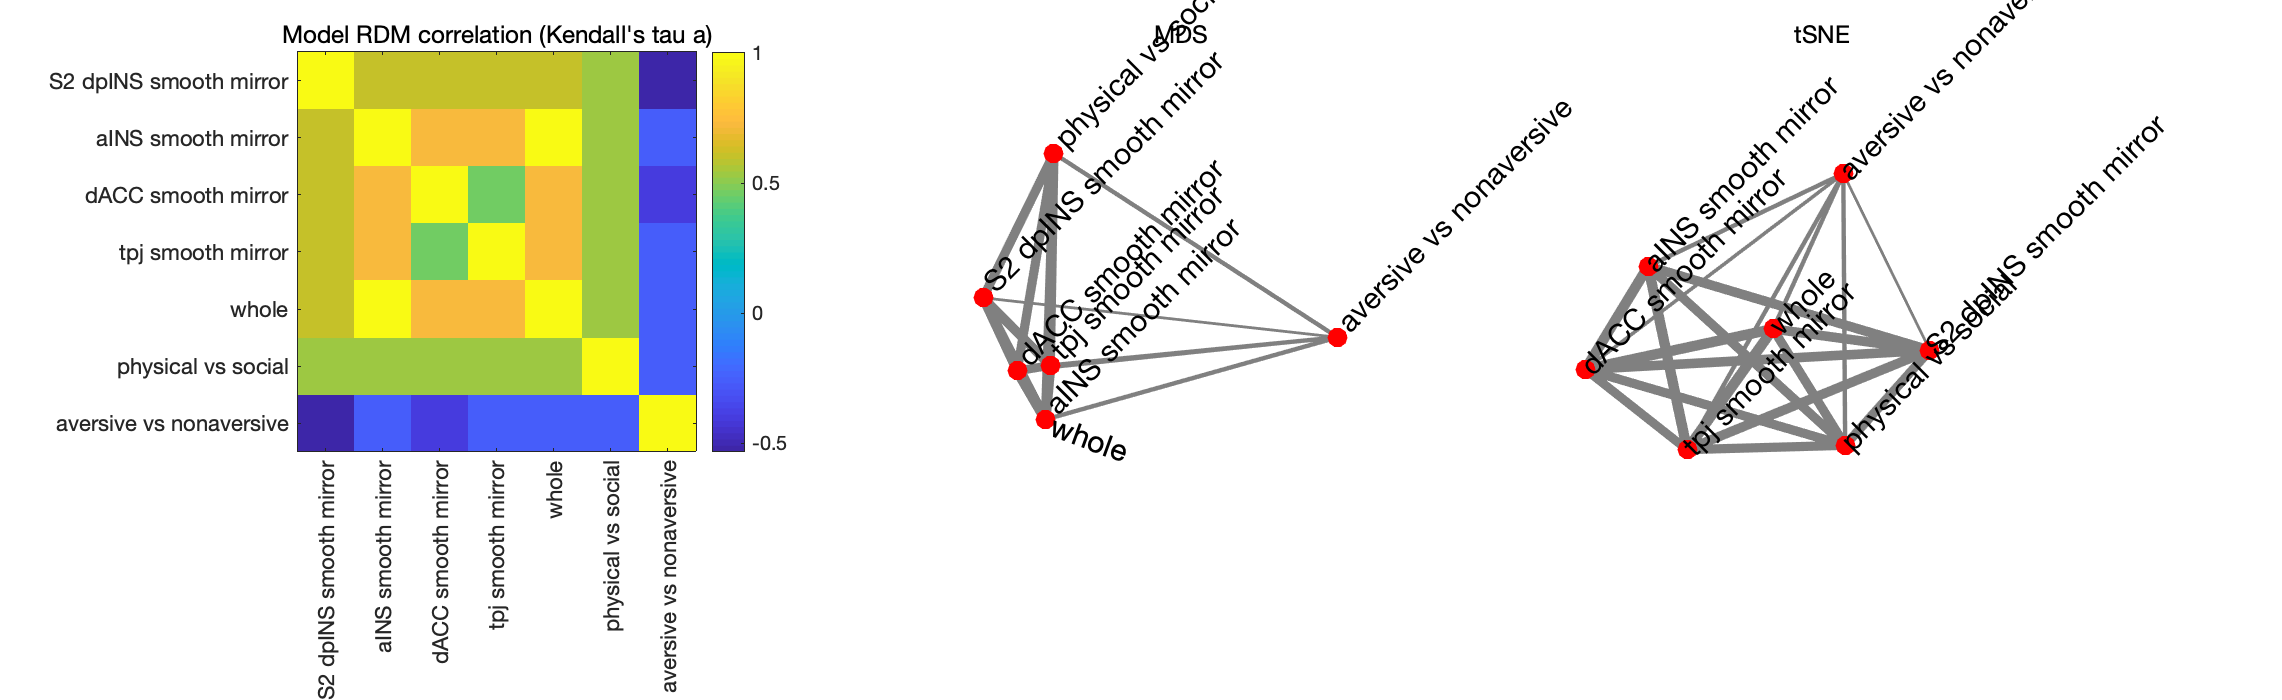

rdm_model = 1-r_models;
Y = mdscale(rdm_model,3);
figure;
set(gcf, 'position', [1         605        1141         350])
subplot(1,3,1);
imagesc(r_models);
set(gca, 'xtick', 1:7, 'ytick', 1:7, 'xticklabel', rdms.names, 'XTickLabelRotation', 90, 'yticklabel', rdms.names);
colorbar;
title('Model RDM correlation (Kendall''s tau a)');

subplot(1,3,2);

for i = 1:size(Y,1)
    for j = 1:size(Y,1)
        if i ~= j
            if rdm_model(i,j) ~= 0
                h = line([Y(i,1), Y(j,1)], [Y(i,2), Y(j,2)], 'linewidth', (2-rdm_model(i,j))*3, 'color', [.5 .5 .5 .1]);
            end
        end
    end
end
hold on;
scatter(Y(:,1), Y(:,2), 100, 'r', 'filled');

text(Y([1:4 6:7],1)+.02, Y([1:4 6:7],2)+.02, rdms.names([1:4 6:7]), 'Rotation', 45, 'fontsize', 15)
text(Y(5,1)+.03, Y(5,2)-.01, rdms.names(5), 'Rotation', -20, 'fontsize', 15)
set(gca, 'xlim', [-0.6 1.5], 'ylim', [-.2 .5]);
axis off;
title('MDS')

subplot(1,3,3);
rng(135)
Y = tsne(rdms.flatten_dat','Algorithm','exact','Distance','correlation', 'Perplexity', 5);
for i = 1:size(Y,1)
    for j = 1:size(Y,1)
        if i ~= j
            if rdm_model(i,j) ~= 0
                h = line([Y(i,1), Y(j,1)], [Y(i,2), Y(j,2)], 'linewidth', (2-rdm_model(i,j))*3, 'color', [.5 .5 .5 .1]);
            end
        end
    end
end
hold on;

scatter(Y(:,1), Y(:,2), 100, 'r', 'filled');

text(Y(:,1)+.100, Y(:,2)+.100, rdms.names, 'Rotation', 45, 'fontsize', 15);
set(gca, 'xlim', get(gca, 'xlim')+[0 200], 'ylim', get(gca, 'ylim')+[0 300]);
title('tSNE')
axis off;

## Step 3: Statistical inference

### Prep for bootstrap tests

% flatten the roi matrix
for roi_i = 1:numel(roi)
    roi{roi_i}.rdms_flatten = [];
    for subj_i = 1:size(roi{roi_i}.rdms,3)
        a = roi{roi_i}.rdms(:,:,subj_i);
        roi{roi_i}.rdms_flatten(:,subj_i) = a(upper_triang_idx);
    end
end
    
model_names = {'phys_soc', 'avers_nonavers'};

for roi_i = 1:numel(roi)
    clear boot_vals;
    for model_i = 1:2
        boot_rdmsmean = bootstrp(10000, @mean, roi{roi_i}.rdms_flatten')';
        for iter_i = 1:size(boot_rdmsmean,2)
            boot_vals(iter_i,1) = rankCorr_Kendall_taua(model{model_i}.rdms(upper_triang_idx), boot_rdmsmean(:,iter_i));
        end
        eval(['roi{roi_i}.bootmean_' model_names{model_i} ' = mean(boot_vals);']);
        eval(['roi{roi_i}.bootste_' model_names{model_i} ' = std(boot_vals);']);
        eval(['roi{roi_i}.bootZ_' model_names{model_i} ' = roi{roi_i}.bootmean_' model_names{model_i} './roi{roi_i}.bootste_' model_names{model_i} ';']);
        eval(['roi{roi_i}.bootP_' model_names{model_i} '= 2 * (1 - normcdf(abs(roi{roi_i}.bootZ_' model_names{model_i} ')));']);
        eval(['roi{roi_i}.ci95_' model_names{model_i} ' = [prctile(boot_vals, 2.5); prctile(boot_vals, 97.5)];']);
    end
end

y = [roi{1}.bootmean_phys_soc, roi{2}.bootmean_phys_soc, roi{3}.bootmean_phys_soc, roi{4}.bootmean_phys_soc];
e = [roi{1}.bootste_phys_soc, roi{2}.bootste_phys_soc, roi{3}.bootste_phys_soc, roi{4}.bootste_phys_soc];

upper_bound = mean(corr(mean(roi{1}.rdms_flatten,2), roi{1}.rdms_flatten));

for i = 1:size(roi{1}.rdms_flatten,2)
    temp = roi{1}.rdms_flatten;
    temp(:,i) = [];
    lower_bound_i(i,1) = corr(mean(temp,2), roi{1}.rdms_flatten(:,i));
end

bar_wani(y, e, .8, 'colors', col, 'errbar_width', 0, 'ast', p, 'ylim', [-2.5 2.5], 'ytick', -2:2, 'ast_adj_x', 0, 'ast_adj_y_neg', .15);